#### Using estimation Data Level_3 and validation data Level_2 MISO)

`case: (1) where measurements are being taken at the excitation point location on the aircraft)`

clear;
ESTIM = load('F16Data_FullMSine_Level3.mat'); 
VALID = load('F16Data_FullMSine_Level2_Validation.mat'); 


% Parameters
N = length(ESTIM.Force); % Number of samples
Fs = ESTIM.Fs;           % Sampling frequency
Ts = 1/Fs;               % Sampling time

%iddata Objects for System Identification
% Estimation data 
% Force and Voltage as inputs
inputs = [ESTIM.Force; ESTIM.Voltage]';

% Acceleration in X, Y, Z as outputs
outputs = [ESTIM.Acceleration(1,:)]';

% iddata object
data_Estimation = iddata(outputs, inputs, Ts);

% Validation data
inputs_Val = [VALID.Force; VALID.Voltage]';
outputs_Val = [VALID.Acceleration(1,:)]';

data_Validation = iddata(outputs_Val, inputs_Val, Ts);
systemIdentification

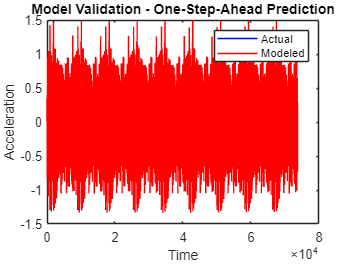

% One-step-ahead prediction on validation data
y_pred = predict(arx661, data_Validation, 1); 

% Plot actual vs modeled output
figure;
plot(data_Validation.OutputData, 'b'); hold on;
plot(y_pred.OutputData, 'r');
legend('Actual', 'Modeled');
title('Model Validation - One-Step-Ahead Prediction');
xlabel('Time');
ylabel('Acceleration');

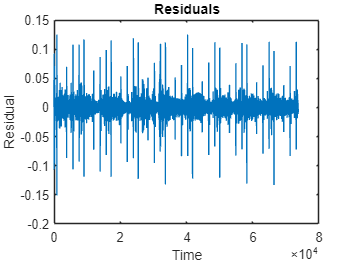


% Compute and plot residuals
residuals = data_Validation.OutputData - y_pred.OutputData;

figure;
plot(residuals);
title('Residuals');
xlabel('Time');
ylabel('Residual');


% Compute fit percentage
fitPercentage = 100 * (1 - norm(data_Validation.OutputData - y_pred.OutputData) / norm(data_Validation.OutputData - mean(data_Validation.OutputData)));
disp(['Fit Percentage: ', num2str(fitPercentage), '%']);

Fit Percentage: 98.3196%



% Calculate one-step-ahead prediction error
predictionError = data_Validation.OutputData - y_pred.OutputData;
NRMSE = sqrt(mean(predictionError.^2)) / std(data_Validation.OutputData);
disp(['Normalized Root Mean Square Error (NRMSE): ', num2str(NRMSE)]);

Normalized Root Mean Square Error (NRMSE): 0.016804
